# Exercise 3

clear; clf; clc; 
s = tf('s');

## Parameters

% PARAMETERS EXERCISE 1
par1.K = 5;             % Gain
par1.T = 4;             % Time constant
par1.u = 1;             % step value
par1.t.start = 0;       % start simulation time
par1.t.stop = 50;       % stop simulation time

% PARAMETERS EXERCISE 2
par2.m = 10;            % mass
par2.C = 100;           % Spring value
par2.D = 3;             % damper value
par2.F = 1;             % force applied
par2.t.start = 0;       % start simulation time
par2.t.stop = 50;       % stop simulation time

% PARAMETERS EXERCISE 3
par3.m1 = 100;          % mass 1
par3.m2 = 10;           % mass 1
par3.C1 = 15;           % Spring value
par3.C2 = 0;            % Spring value
par3.D2 = 0;            % damper value
par3.t.start = 0;       % start simulation time
par3.t.stop = 1000;       % stop simulation time


## Execise a)

Simulate the step response of the transfer-function PT1 **G(s) = K/(1+Ts)** with K = 5 and T = 4 sec as differential equation and transfer-function: Display the results in a plot window and export the results to the Matlab workspace. Remember the differential equation of a PT1 is:

** ẋ = 1/T (K ⋅ 𝑢 − x)**

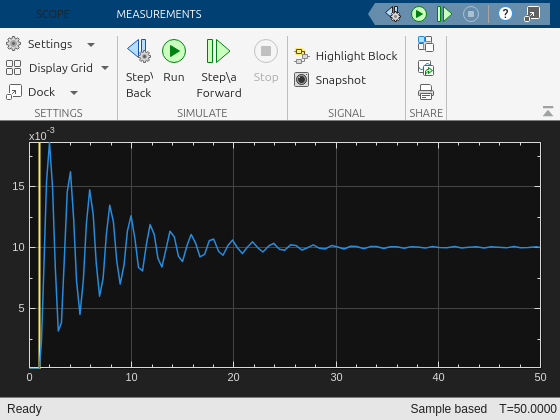

G1 = par1.K/(1+par1.T*s);     % transfer function

G1_de = @(t,x) 1/par1.T*(par1.K*par1.u - x);

[t1,y1] = ode45(G1_de,[par1.t.start par1.t.stop],0);

out1 = sim('exercise3_SIM');     % simulate the system with simulink and get the scope datas

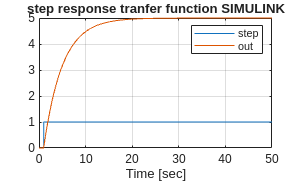


figure()
plot(out1.plotG1_Tf.time,out1.plotG1_Tf.signals(1).values,...       % Plot the result of the simulation
    out1.plotG1_Tf.time,out1.plotG1_Tf.signals(2).values)
grid on, xlabel('Time [sec]');legend('step','out'); title('step response tranfer function SIMULINK');

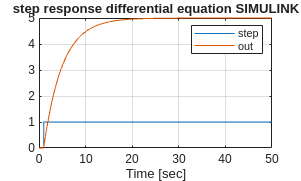


figure()
plot(out1.plotG1_De.time,out1.plotG1_De.signals(1).values,...       % Plot the result of the simulation
    out1.plotG1_De.time,out1.plotG1_De.signals(2).values)
grid on, xlabel('Time [sec]');legend('step','out'); title('step response differential equation SIMULINK');

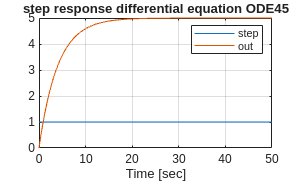


figure()
plot([par1.t.start par1.t.stop], [par1.u par1.u],t1,y1)
grid on, xlabel('Time [sec]');legend('step','out'); title('step response differential equation ODE45');



% function [dz] = G1_de(t,x,par1)
%     dx = 1/par1.T*(par1.K*par1.U - x);
%     dz = [x,dx];
% end

## Exercise b)

Build up the model of a one-mass spring system in Simulink

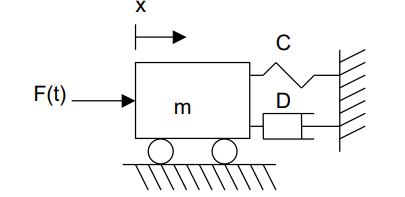

**Moving mass model** 

 with m = 10 kg; C=100 N/m; D=3 N*sec/m; Calculate the step response and investigate the influence of the physical parameters on the simulation results!

initialState1 = [0;0];
[t2,y2] = ode45(@(t,z) massDgl(t,z,par2),[par2.t.start par2.t.stop],initialState1);

out2 = sim("exercise3_SIM.slx");

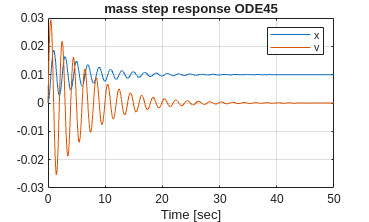


plot(t2,y2)
grid on, xlabel('Time [sec]');legend('x','v'); title('mass step response ODE45');

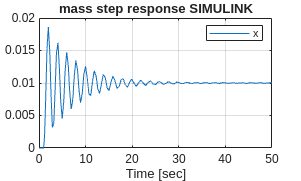


plot(out2.plotE2.time,out2.plotE2.signals(2).values)
grid on, xlabel('Time [sec]');legend('x'); title('mass step response SIMULINK');



function [dz] = massDgl(t,z,par2)
    x = z(1);
    v = z(2);

    dv = 1/par2.m*(-par2.C*x - par2.D*v + par2.F);

    dx = v;

    dz = [dx;dv];
end



## Exercise c)

Derive the equations for the two mass systems. Optimize the Spring C2 and D2 in a way, that the mass m2=10 kg damps the oscillation of mass m1=100 kg with spring C1=15 N/m using a Simulink simulation model.

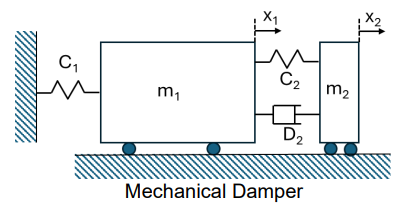

SOLUTION:

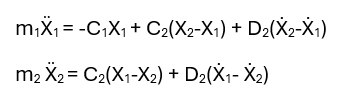

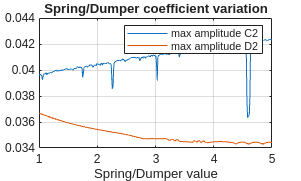

initialState2 = [0.1;0;0;0];

maxValuesC = [];
par3.D2 = 0;
for i = 1:0.01:5
    par3.C2 = i;
    [t4,y4] = ode45(@(t,z) dualMassDgl(t,z,par3),[par3.t.start par3.t.stop],initialState2);
    maxValuesC = [maxValuesC;i, max(y4(:,2))];
end

maxValuesD = [];
par3.C2 = 0;
for i = 1:0.01:5
    par3.D2 = i;
    [t5,y5] = ode45(@(t,z) dualMassDgl(t,z,par3),[par3.t.start par3.t.stop],initialState2);
    maxValuesD = [maxValuesD;i, max(y5(:,2))];
end

[bestC2Amplitude, bestC2Index]  = min(maxValuesC(:,2));
[bestD2Amplitude, bestD2Index] = min(maxValuesD(:,2));

par3.C2 = maxValuesC(bestC2Index,1);
par3.D2 = maxValuesD(bestD2Index,1);

[t3,y3] = ode45(@(t,z) dualMassDgl(t,z,par3),[par3.t.start par3.t.stop],initialState2);

figure()
plot(maxValuesC(:,1),maxValuesC(:,2),maxValuesD(:,1),maxValuesD(:,2))
grid on, xlabel('Spring/Dumper value');legend('max amplitude C2','max amplitude D2'); title('Spring/Dumper coefficient variation');

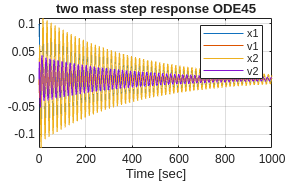


figure()
plot(t3,y3(:,1),t3,y3(:,2),t3,y3(:,3),t3,y3(:,4))
grid on, xlabel('Time [sec]');legend('x1','v1','x2','v2'); title('two mass step response ODE45');

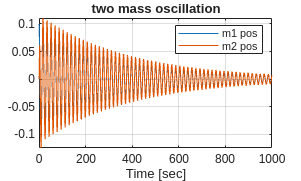


figure()
plot(t3,y3(:,1),t3,y3(:,3))
grid on, xlabel('Time [sec]');legend('m1 pos','m2 pos'); title('two mass oscillation');




function [dz] = dualMassDgl(t,z,par3)
    x1 = z(1);
    v1 = z(2);
    x2 = z(3);
    v2 = z(4);

    dv1 = 1/par3.m1*(-par3.C1*x1 + par3.C2*(x2-x1) + par3.D2*(v2-v1));
    dv2 = 1/par3.m2*(par3.C2*(x1-x2) + par3.D2*(v1-v2));

    dz = [v1;dv1;v2;dv2];
end